验证一下那篇论文里的各种数据，作图分析作图分析

kd0按照波长为x，衰减系数为y进行作图

kd_0_wl_1 = [0.173,0.151,0.0619,0.0377,0.0284,0.0222,0.0192, 0.0182,0.0284,0.0398,0.0598,0.0834,0.163,0.301,0.357,0.416,0.528]

kd_0_wl_1 =     0.1730    0.1510    0.0619    0.0377    0.0284    0.0222    0.0192    0.0182    0.0284    0.0398    0.0598    0.0834    0.1630    0.3010    0.3570    0.4160    0.5280


kd_0_wl_1a = [0.223,0.186,0.078,0.050,0.0377,0.0294,0.0263,0.0253,0.0346,0.0460,0.0661,0.0943,0.174,0.308,0.364,0.423,0.536]

kd_0_wl_1a =     0.2230    0.1860    0.0780    0.0500    0.0377    0.0294    0.0263    0.0253    0.0346    0.0460    0.0661    0.0943    0.1740    0.3080    0.3640    0.4230    0.5360


kd_0_wl_1b = [0.288,0.223,0.0998,0.0619,0.0460,0.0367,0.0336,0.0325,0.0408,0.0513,0.0726,0.0998,0.186,0.315,0.371,0.431,0.545];
kd_0_wl_2 = [0.439,0.371,0.174,0.116,0.0834,0.0672,0.0619,0.0619,0.0672,0.0780,0.0998,0.134,0.223,0.342,0.393,0.454,0.580];
kd_0_wl_3 = [0.837, 0.693,0.342,0.236,0.174,0.139,0.122,0.117,0.116,0.122,0.145,0.192,0.288,0.386,0.431,0.494,0.616];

kd_0_wl_1c = [3.244,2.577,1.204,0.616,0.371,0.236,0.174,0.134,0.119,0.122,0.145,0.192,0.288,0.386,0.431,0.494,0.616];
kd_0_wl_3c = [5.705,4.507,1.772,1.079,0.635,0.416,0.288,0.223,0.198,0.198,0.211,0.248,0.342,0.431,0.478,5.705,4.507];
kd_0_wl_5c = [6.42,5.33,2.43,1.56,1.02,0.693,0.511,0.400,0.342,0.315,0.329,0.357,6.42,5.33,2.43,1.56,1.02];
kd_0_wl_7c = [6.92,5.91,3.00,2.12,1.51,1.14,0.868,0.693,0.580,0.494,0.462,0.462,0.478,0.545,0.635,0.777,0.916]

kd_0_wl_7c =     6.9200    5.9100    3.0000    2.1200    1.5100    1.1400    0.8680    0.6930    0.5800    0.4940    0.4620    0.4620    0.4780    0.5450    0.6350    0.7770    0.9160


kd_0_wl_9c = [8.11,7.01,4.30,3.06,2.41,1.90,1.56,1.24,1,0.777,0.635,0.580,0.598,0.654,0.755,0.916,1.11];


画图，横轴为波长，纵轴为衰减系数

x=[300 310 350 375 400 425 450 475 500 525 550 575 600 625 650 675 700]%x轴上的数据，第一个值代表数据开始，第二个值代表间隔，第三个值代表终止

x =    300   310   350   375   400   425   450   475   500   525   550   575   600   625   650   675   700


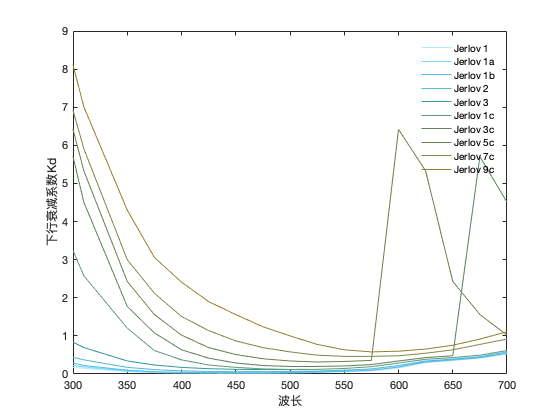


l1 = plot(x,kd_0_wl_1,'Color', [0.6993	0.9166	1]);
hold on;
l1a = plot(x,kd_0_wl_1a, 'Color', [0.4917	0.8378	1]);
hold on;
l1b = plot(x,kd_0_wl_1b, 'Color', [0.3232	0.7504	0.9206]);
hold on;
l2 = plot(x,kd_0_wl_2, 'Color', [0.3494	0.7157	0.8467]);
hold on;
l3 = plot(x,kd_0_wl_3, 'Color', [0.2223	0.5959	0.6421]);
hold on;

l1c = plot(x,kd_0_wl_1c, 'Color', [0.3796	0.6045	0.4869]);
hold on;
l3c = plot(x,kd_0_wl_3c, 'Color', [0.3784	0.5113	0.3644]);
hold on;
l5c = plot(x,kd_0_wl_5c, 'Color', [0.4200	0.5140	0.3091]);
hold on;
l7c = plot(x,kd_0_wl_7c, 'Color', [0.5197	0.5305	0.2916]);
hold on;
l9c = plot(x,kd_0_wl_9c, 'Color', [0.5854	0.5075	0.1873]);
hold off;

% axis([300,700,0,10])  %确定x轴与y轴框图大小
% set(gca,'XTick',[250:25:750]) %x轴范围1-6，间隔1
% set(gca,'YTick',[0:0.1:10]) %y轴范围0-700，间隔100


legend([l1(1),l1a(1),l1b(1),l2(1),l3(1),l1c(1),l3c(1),l5c(1),l7c(1),l9c(1)],'Jerlov 1','Jerlov 1a','Jerlov 1b','Jerlov 2','Jerlov 3','Jerlov 1c','Jerlov 3c','Jerlov 5c','Jerlov 7c','Jerlov 9c');   %右上角标注
legend('boxoff')
xlabel('波长')  %x轴坐标描述
ylabel('下行衰减系数Kd') %y轴坐标描述